# **Miniproject #1**

## Author : Mrinmoy Sarkar

## Date : 11/21/2017

## Email : msarkar@aggies.ncat.edu

## Bannar Id: 950-363-260

# **{a}**

# **# Parameters for the Selected System**

%% parameters
M = 30

M = 30

mw = 2

mw = 2

r = 0.1

r = 0.1000

d = 0.7

d = 0.7000

K_tL = 0.5

K_tL = 0.5000

K_tR = 0.5

K_tR = 0.5000

B_L = 0.1

B_L = 0.1000

B_R = 0.1

B_R = 0.1000

J_m = 0.0263

J_m = 0.0263

J_M = 2.45

J_M = 2.4500


alpha = M*r^2 + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)/2 - ...
    2*J_M^2*(r^2/d^2)/(M*r^2) + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)

alpha = -0.1639


beta = 2*J_M^2*(r^4/d^4)/(M*r^2) + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)

beta = 0.2056


gama = 2*J_M*(r^2/d^2)/(M*r^2) + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)

gama = 0.5222

# **# State-Space Representation of the System**

%% system matrix
A = [0     1        0        0     0          0;...
     0 -B_L/alpha -1/alpha   0 beta/alpha gama/alpha;...
     0     0        0        0     0          0;...
     0     0        0        0    1/alpha     0;...
     0 beta/alpha gama/alpha 0 -B_R/alpha -1/alpha;...
     0     0        0        0     0          0]

A =          0    1.0000         0         0         0         0
         0    0.6103    6.1025         0   -1.2545   -3.1869
         0         0         0         0         0         0
         0         0         0         0   -6.1025         0
         0   -1.2545   -3.1869         0    0.6103    6.1025
         0         0         0         0         0         0


 
 B = [    0                 0;...
      K_tL/alpha 2*K_tL*gama/alpha;...
          0                 0;...
          0                 0;...
      2*K_tR*gama/alpha K_tR/alpha;...
          0                 0]

B =          0         0
   -3.0513   -3.1869
         0         0
         0         0
   -3.1869   -3.0513
         0         0


   
 C = [1 1 0 1 1 0]

C =      1     1     0     1     1     0


 D = [0 0]

D =      0     0



$$$\dot{\mathbf{x}} = A\mathbf{x} + BU\\
y = C\mathbf{x} + DU$$$


                                                     where,

                                                       $$A = \pmatrix{0 & 1 & 0 & 0 & 0 & 0 \cr
0 & 0.6103 & 6.1025 & 0 & -1.2545 & -3.1869 \cr 
0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & -6.1025 & 0 \cr 
0 & -1.2545 & -3.1869 & 0 & 0.6103 & 6.1025 \cr
0 & 0 & 0 & 0 & 0 & 0 
}$$ , $$B = \pmatrix{
         0      &   0 \cr
   -3.0513  & -3.1869 \cr
         0        & 0 \cr
         0       &  0 \cr
   -3.1869  & -3.0513 \cr
         0      &   0 

}
$$

$$C=\pmatrix{1 &1 &0 &1 &1 &0}
$$ , $$
D=\pmatrix{0&0}
$$

# **# Check the Controllability of the System**

**Step1: find the C matrix;**

**Where,** $$
C=\pmatrix{B&BA&BA^2&BA^3&BA^4&BA^5}
$$

Ct = ctrb(A,B)

Ct =          0         0   -3.0513   -3.1869    2.1359    1.8829   -1.0586   -1.5304    1.2738    0.3941    0.2830   -1.3575
   -3.0513   -3.1869    2.1359    1.8829   -1.0586   -1.5304    1.2738    0.3941    0.2830   -1.3575    1.8756   -1.1834
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   19.4484   18.6204  -11.4904  -13.0344    9.3393    6.4602   -2.4048   -7.7735    8.2841   -1.7270
   -3.1869   -3.0513    1.8829    2.1359   -1.5304   -1.0586    0.3941    1.2738   -1.3575    0.2830   -1.1834    1.8756
         0         0         0         0         0         0         0         0         0         0         0         0



$$$
C = \pmatrix{ 0        &  0 &  -3.0513&   -3.1869&    2.1359 &   1.8829&   -1.0586&   -1.5304&    1.2738 &   0.3941 &   0.2830 &  -1.3575\cr
   -3.0513  & -3.1869 &   2.1359&    1.8829&   -1.0586&   -1.5304&    1.2738&    0.3941&    0.2830&   -1.3575&    1.8756&   -1.1834\cr
         0   &      0 &        0 &        0  &       0&         0    &     0  &       0  &       0    &     0    &     0   &      0\cr
         0   &      0  & 19.4484 &  18.6204&  -11.4904 & -13.0344  &  9.3393  &  6.4602  & -2.4048  & -7.7735   & 8.2841 &  -1.7270\cr
   -3.1869 &  -3.0513 &   1.8829 &   2.1359 &  -1.5304 &  -1.0586 &   0.3941   & 1.2738 &  -1.3575  &  0.2830 &  -1.1834  &  1.8756\cr
         0     &    0    &     0   &      0  &       0&         0      &   0    &     0   &      0       &  0     &    0   &      0
}
$$$


**Step2: find the rank of C matrix and check if C is full row rank or not**

rnk = rank(Ct)

rnk = 4

controllable = rank(Ct) == size(Ct,1)

controllable = logical
   0


## **So, **$$
\rho(C) \neq r
$$** and thats why the system is not controllable.**

# **# Check if the system is Stable or not**

[num,den] = ss2tf(A,B,C,D,2)

num =          0   -6.2382   27.0660  -29.9881   -0.0000         0         0


den =     1.0000   -1.2205   -1.2013         0         0         0         0


sys = tf(num,den)


sys =
 
                              
  -6.238 s^5 + 27.07 s^4      
                              
          - 29.99 s^3         
                              
               - 8.792e-15 s^2
                              
  ----------------------------
                             
  s^6 - 1.221 s^5 - 1.201 s^4
                             
 
Continuous-time transfer function.




stability = isstable(sys)

stability = logical
   0


pl = pole(sys)

pl =          0
         0
         0
         0
    1.8647
   -0.6442


## **Remark: The System is not stable**

# **# Decompose the System into Controllable and Uncontrollolable part**

If the controllability matrix of (*A*, *B*) has rank *r* ≤ *n*, where *n* is the size of *A*, then there exists a similarity transformation such that


$$$
\bar{A} = TAT^T, \bar{B}=TB,\bar{C}=CT^T
$$$


where *T* is unitary, and the transformed system has a *staircase* form, in which the uncontrollable modes, if there are any, are in the upper left corner.


$$$
\bar{A}=\pmatrix{A_{\bar{c}}&0\cr A_{21} & A_{c}},\bar{B}=\pmatrix{0\cr B_{c}},\bar{C}=\pmatrix{C_{\bar{c}}&C_{c}}
$$$


where ($$A_{c},B_{c}$$) is controllable, all eigenvalues of $$A_{\bar{c}}$$ are uncontrollable, and $$C_c(sI-A_c)^{-1}B_c=C(sI-A)^{-1}B$$.

`[Abar,Bbar,Cbar,T,k] = ctrbf(A,B,C)` decomposes the state-space system represented by `A`, `B`, and `C` into the controllability staircase form, `Abar`, `Bbar`, and `Cbar`, described above. `T` is the similarity transformation matrix and `k` is a vector of length *n*, where *n* is the order of the system represented by `A`. Each entry of `k` represents the number of controllable states factored out during each step of the transformation matrix calculation. The number of nonzero elements in `k` indicates how many iterations were necessary to calculate `T`, and `sum(k)`is the number of states in $A_c$, the controllable portion of `Abar`.

[Abar,Bbar,Cbar,T,kbar] = ctrbf(A,B,C)

**Extract the Controllable and Uncontrollable part from Abar, Bbar and Cbar:**

Ac = Abar(size(Abar,1)-sum(kbar)+1:end,size(Abar,1)-sum(kbar)+1:end)

Ac =     0.0000    0.0000    0.7071   -0.7071
   -0.0000    0.0000   -4.3151   -4.3151
    0.0000    0.0000    1.8647    0.0000
    0.0000    0.0000         0   -0.6442


Bc = Bbar(size(Abar,1)-sum(kbar)+1:end,:)

Bc =    -0.0000   -0.0000
    0.0000    0.0000
   -0.0959    0.0959
   -4.4111   -4.4111


Cc = Cbar(size(Abar,1)-sum(kbar)+1:end)

Cc =    -1.0000    1.0000    0.0000    1.4142


Dc = zeros(1,size(Bc,2))

Dc =      0     0



Auc = Abar(1:size(Abar,1)-sum(kbar),1:size(Abar,1)-sum(kbar))

Auc =    1.0e-29 *

         0         0
    0.6537   -0.6860


Buc = Bbar(1:size(Bbar,1)-sum(kbar),1:2)

Buc =    1.0e-30 *

         0         0
    0.4438    0.2482


Cuc = Cbar(1:size(Abar,1)-sum(kbar))

Cuc =    1.0e-15 *

         0    0.9992


Duc = zeros(1,size(Buc,2))

Duc =      0     0


**Now Check if the uncontrollable part is stable or not:**

[num,den] = ss2tf(Auc,Buc,Cuc,Duc,2)

num =    1.0e-45 *

         0    0.2480         0


den =     1.0000    0.0000         0


sys = tf(num,den)


sys =
 
     2.48e-46 s
  ----------------
  s^2 + 6.86e-30 s
 
Continuous-time transfer function.



stability = isstable(sys)

stability = logical
   0


pl = round(pole(sys),4)

pl =      0
     0


**Remark: The uncontrollable part has poles which values are zero, means on imaginary axis. so, the system is marginally stable**

# **# Design of State-Feedback Controller for the Controllable Part**

**Step1: Check if **$(A_c , B_c)$ **is controllable or not**

Ct = ctrb(Ac,Bc)

Ct =    -0.0000   -0.0000    3.0513    3.1869   -2.1359   -1.8829    1.0586    1.5304
    0.0000    0.0000   19.4484   18.6204  -11.4904  -13.0344    9.3393    6.4602
   -0.0959    0.0959   -0.1789    0.1789   -0.3336    0.3336   -0.6221    0.6221
   -4.4111   -4.4111    2.8417    2.8417   -1.8307   -1.8307    1.1794    1.1794


controllable = rank(Ct) == size(Ct,1)

controllable = logical
   1


**So, **$(A_c , B_c)$ **is controllable**

**Step2: Check if eigen values of **$A_c$ **are distinct or not**

ev = round(eig(Ac), 4)

ev =     1.8647
   -0.6442
         0
         0


fprintf('%d\n',ev)

1.864700e+00
-6.442000e-01
0
0


iseigdistinct = length(ev) == length(unique(ev))

iseigdistinct = logical
   0


**So, All eigen values of **$A_c
$** are not distinct**

**Step3: Now let, randomly select **$K_1
$

K1 = zeros(size(Bc'));
K1(1,1) = 1

K1 =      1     0     0     0
     0     0     0     0


K1(2,2) = 1

K1 =      1     0     0     0
     0     1     0     0


**Check if the eigenvalues of **$A_c-B_cK_1$

ev = round(eig(Ac-Bc*K1), 4)

ev =   -0.3336 + 4.6748i
  -0.3336 - 4.6748i
  -0.1173 + 0.0000i
   2.0050 + 0.0000i


iseigdistinct = length(ev) == length(unique(ev))

iseigdistinct = logical
   1


**So, the eigen values are distinct**

**Check if **$(A_c -B_cK_1, B_c)$ **is controllable or not**

Ct = ctrb(Ac-Bc*K1,Bc)

Ct =    -0.0000   -0.0000    3.0513    3.1869   -2.1359   -1.8829  -70.2324  -67.5359
    0.0000    0.0000   19.4484   18.6204  -11.4904  -13.0344 -412.1392 -402.2396
   -0.0959    0.0959   -0.1789    0.1789   -1.9067   -1.1471   -2.6581   -1.0691
   -4.4111   -4.4111    2.8417    2.8417   97.4169   94.3631 -122.8648 -126.5920


controllable = rank(Ct) == size(Ct,1)

controllable = logical
   1


**So,** $(A_c -B_cK_1, B_c)$ **is controllable**

**Now define, **$A_1=A_c-B_cK_1$

A1 = Ac - Bc*K1

A1 =     0.0000    0.0000    0.7071   -0.7071
   -0.0000    0.0000   -4.3151   -4.3151
    0.0959   -0.0959    1.8647    0.0000
    4.4111    4.4111         0   -0.6442


**Step4: Now randomly select q** 

q = [1 0]'

q =      1
     0


**Step5: let **$B_1 = B_cq$

B1 = Bc*q

B1 =    -0.0000
    0.0000
   -0.0959
   -4.4111


**Step6: Check if **$(A1,B1)$** is controllable or not**

Ct = ctrb(A1,B1)

Ct =    -0.0000    3.0513   -2.1359  -70.2324
    0.0000   19.4484  -11.4904 -412.1392
   -0.0959   -0.1789   -1.9067   -2.6581
   -4.4111    2.8417   97.4169 -122.8648


controllable = rank(Ct) == size(Ct,1)

controllable = logical
   1


**So, **$(A_1 , B_1)$ **is controllable**

**Step7: Now find **$K^T$ **by using Ackermann’s Formula**

**First, define the desired poles using  ITAE prototype**

poles = [-0.424+1.263i -0.424-1.263i ...
              -0.6260+0.4141i -0.6260-0.4141i]

poles =   -0.4240 + 1.2630i  -0.4240 - 1.2630i  -0.6260 + 0.4141i  -0.6260 - 0.4141i


**Now, find the Characteristic polynomial **$\Delta_d(\lambda)$**using these poles**

del_d_lambda = poly(poles)

del_d_lambda =     1.0000    2.1000    3.4000    2.7000    0.9999


**So, **$\Delta_d(\lambda) = \lambda^4+2.1\lambda^3+3.4\lambda^2+2.7\lambda+0.9999$

**Now, find **$\Delta_d(A_1)$

del_d_A1 = zeros(size(A1));
for i=1:length(del_d_lambda)-1
    del_d_A1 = del_d_A1 + del_d_lambda(i)*A1^(length(del_d_lambda)-i);
end
del_d_A1 = del_d_A1 + del_d_lambda(end)*eye(size(A1))

del_d_A1 =    65.3434   60.6544   55.4950   12.7381
  370.1446  367.3024  117.4223   67.8148
    7.5295    2.6107   48.7258   -4.5061
  -79.4627  -69.3225  207.1798  442.5872


**Now, find **$K^T$** using Ackermann’s Formula**

K_T = [0 0 0 1]*pinv(Ct)*del_d_A1

K_T =    -1.1936   -0.4522   -6.4706   -0.6120


**Step8: Now find Feedback gain K**

K = K1 + q*K_T

K =    -0.1936   -0.4522   -6.4706   -0.6120
         0    1.0000         0         0


**Step9: Find the FeedForword gain F using the formula given below:**

For asymtotic tracking, $C(-A+BK^T)^{-1}BF = 1$

where, $F=\pmatrix{F_1\cr F_2}$


coeff = Cc*pinv(-Ac+Bc*K)*Bc

coeff =     5.1655    3.3357


So, $5.1655F_1+3.3357F_2 = 1$

let, $F_1 = 1$

F1 = 1

F1 = 1

F2 = (1-coeff(1))/coeff(2)

F2 = -1.2488

F=[F1;F2]

F =     1.0000
   -1.2488


**So, the Controller input is : **$u(t)=-K^Tx(t)+Fr(t)$

**where, **$K^T=10^{13}\pmatrix{1.8428& -0.3065& -1.4081& 0.0306\cr0& 0& 0&0}$ **and **$F=\pmatrix{1\cr-1.2488}$

# **{b}**

# **# State space  representation of the closed loop system**

%K=place(Ac,Bc,poles)
AcL = Ac-Bc*K

AcL =     0.0000    0.0000    0.7071   -0.7071
   -0.0000    0.0000   -4.3151   -4.3151
   -0.0186   -0.1393    1.2439   -0.0587
   -0.8539    2.4165  -28.5422   -3.3439


BcL = Bc*F

BcL =    -0.0000
    0.0000
   -0.2157
    1.0973


CcL = Cc

CcL =    -1.0000    1.0000    0.0000    1.4142


DcL = [0]

DcL = 0

**State Space Representation of Closed-loop System:**


$$$\dot{\mathbf{x}} = A_{cL}\mathbf{x} + B_{cL}U\\
y = C_{cL}\mathbf{x} + D_{cL}U$$$


**Plot the step response of the closed loop system:**

sys = tf(ss(AcL,BcL,CcL,DcL))


sys =
 
                              
  1.552 s^3 + 3.903 s^2       
                              
            - 10.89 s + 0.9999
                              
  ----------------------------
                              
  s^4 + 2.1 s^3 + 3.4 s^2     
                              
              + 2.7 s + 0.9999
                              
 
Continuous-time transfer function.



**Define the time vector:**

%step(sys)
dt = 0.01;
tFinal = 30;
t = 0:dt:tFinal;
n = length(t);

**Define the reference signal:**

r = ones(1,n);

**Plot the system response:**

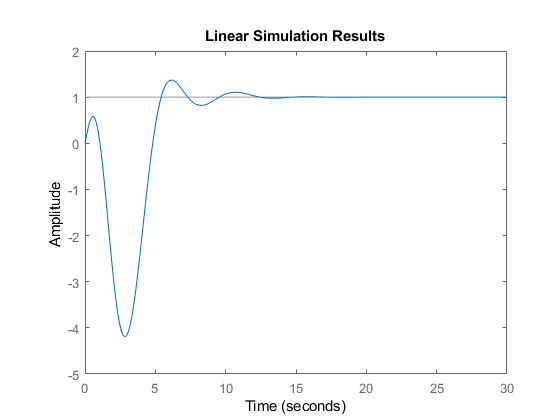

lsim(sys,r,t);

## **Remark:**$y(t)$** asymptotically tracks the reference signal**

# **{c}**

# **# Simulation of the system by adding disturbance**

**Adding disturbance after 10 second:**

n1 = find(t==10);

**Define the distubance:**

w = [zeros(1,n1) ones(1,n-n1)]';
w =[w w];

**Define the u matrix:**

u = [r' w];

**Define new B matrix:**

Bd = [Bc*F Bc]

Bd =    -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000
   -0.2157   -0.0959    0.0959
    1.0973   -4.4111   -4.4111


Dd = [0 0 0];
sys = tf(ss(AcL,Bd,CcL,Dd))


sys =
 
  From input 1 to output:
                              
  1.552 s^3 + 3.903 s^2       
                              
            - 10.89 s + 0.9999
                              
  ----------------------------
                              
  s^4 + 2.1 s^3 + 3.4 s^2     
                              
              + 2.7 s + 0.9999
                              
 
  From input 2 to output:
                              
  -6.238 s^3 + 28.03 s^2      
                              
              - 24.2 s + 5.165
                              
  ----------------------------
                              
  s^4 + 2.1 s^3 + 3.4 s^2     
                              
              + 2.7 s + 0.9999
                              
 
  From input 3 to output:
                              
  -6.238 s^3 + 19.32 s^2      
                              
             - 10.66 s + 3.335
                              
  ----------------------------
                              
  s^4 + 2.

**Plot the step responce in the presence of disturbance:**

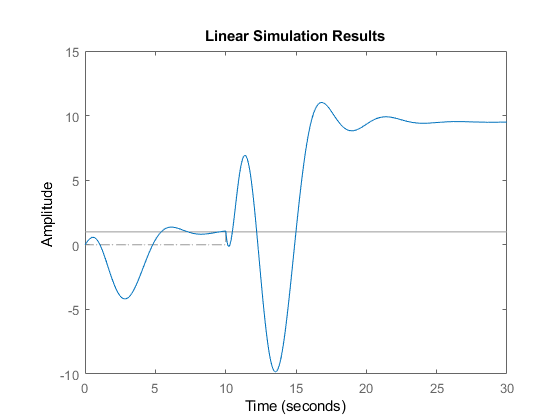

lsim(sys,u,t);

## **Remark:**$y(t)$** does not asymptotically tracks the reference signal**

# **{d}**

# **# Design of an Integral Controller**

**Add a new pole for the integral controller:**


poles = [poles -0.8955]

poles =   -0.4240 + 1.2630i  -0.4240 - 1.2630i  -0.6260 + 0.4141i  -0.6260 - 0.4141i  -0.8955 + 0.0000i


**Calculate new State Space matrix:**


$$\dot\bar{X} =\pmatrix{A_c&0\cr-C_c &0}\bar{X}+\pmatrix{B_c\cr 0}u+\pmatrix{B_c\cr0}w+\pmatrix{0\cr1}r\\
y=\pmatrix{C_c&0}\bar{X}\\
u=-\pmatrix{K^T &-K_I}\bar{X}$$


Ai = zeros(size(Ac,1)+1);
Ai(1:4,1:4) = Ac;
Ai(5,1:4) = -Cc;
Bi = zeros(size(Bc,1)+1,2);
Bi(1:4,1:2) = Bc

Bi =    -0.0000   -0.0000
    0.0000    0.0000
   -0.0959    0.0959
   -4.4111   -4.4111
         0         0


Ci = zeros(1,size(Cc,2)+1);
Ci(1,1:4) = Cc

Ci =    -1.0000    1.0000    0.0000    1.4142         0


Di = zeros(size(Ci,1),size(Bi,2));
k = place(Ai,Bi,poles)

k =    -3.7315    2.6384  -18.5202    0.5970   -1.9805
    3.8372   -2.6434   18.5377   -0.7467    2.0044


**Calculate the new Closed loop Syatem when W=0:**

K_T = k(1:2,1:4)

K_T =    -3.7315    2.6384  -18.5202    0.5970
    3.8372   -2.6434   18.5377   -0.7467


K_I = -k(:,end)

K_I =     1.9805
   -2.0044


Aicl=Ai;
Aicl(1:4,1:4) = Ac - Bc*K_T;
Aicl(1:4,5) = Bc*K_I

Aicl =    -0.0000    0.0000    0.7071   -0.7071   -0.0000
   -0.0000    0.0000   -4.3151   -4.3151    0.0000
   -0.7261    0.5067   -1.6906    0.1289   -0.3823
    0.4663   -0.0219    0.0769   -1.3049    0.1056
    1.0000   -1.0000   -0.0000   -1.4142         0


Bi=[0 0 0 0 1]';
Di = zeros(size(Ci,1),size(Bi,2));

**New closeloop system w=0:**


$$\dot\bar{X} =\pmatrix{A_c-BK^T&BK_I\cr-C_c &0}\bar{X}+\pmatrix{0\cr1}r\\
y=\pmatrix{C_c&0}\bar{X}$$


where, $K^T=\pmatrix{-3.7315  &  2.6384&  -18.5202  &  0.5970\cr
    3.8372 &  -2.6434   &18.5377   & -0.7467}\\

K_I=\pmatrix{1.9805\cr-2.0044}$

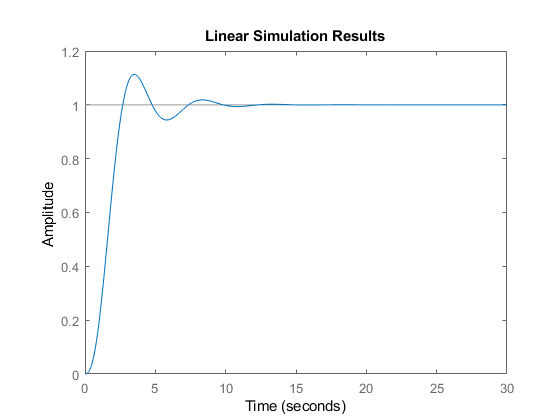

syscl = tf(ss(Aicl,Bi,Ci,Di));
     
r = ones(1,n);
lsim(syscl,r,t);

# **{e}**

# **# Simulation of the Integral controller Closed- loop system by adding disturbance**


Bi=[Bc zeros(4,1);0 0 1]

Bi =    -0.0000   -0.0000         0
    0.0000    0.0000         0
   -0.0959    0.0959         0
   -4.4111   -4.4111         0
         0         0    1.0000


Di = zeros(size(Ci,1),size(Bi,2));

**New Closed loop system when w = 1 for t>10:**


$$\dot\bar{X} =\pmatrix{A_c-BK^T&BK_I\cr-C_c &0}\bar{X}+\pmatrix{B\cr0}w+\pmatrix{0\cr1}r\\
y=\pmatrix{C_c&0}\bar{X}$$


syscl = tf(ss(Aicl,Bi,Ci,Di))


syscl =
 
  From input 1 to output:
                              
  -6.238 s^4 + 5.84 s^3       
                              
          + 13.52 s^2         
                              
                     + 6.166 s
                              
  ----------------------------
                              
  s^5 + 2.995 s^4 + 5.281 s^3 
                              
          + 5.745 s^2         
                              
            + 3.418 s + 0.8954
                              
 
  From input 2 to output:
                              
  -6.238 s^4 + 4.898 s^3      
                              
          + 12.32 s^2         
                              
                     + 5.646 s
                              
  ----------------------------
                              
  s^5 + 2.995 s^4 + 5.281 s^3 
                              
          + 5.745 s^2         
                              
            + 3.418 s + 0.8954
                              
 
  F

**Plot the step responce in the presence of disturbance:**

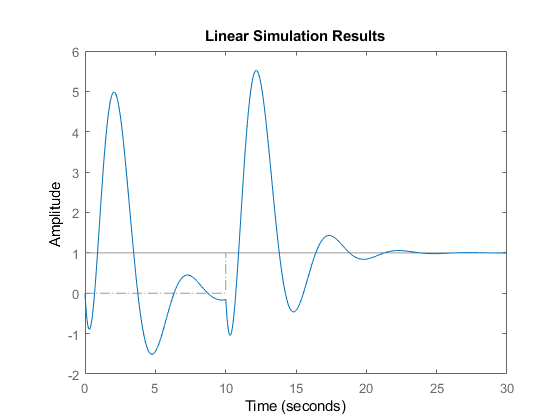

lsim(syscl,u,t)

## **Remark:**$y(t)$**asymptotically tracks the reference signal**

# **{f}**

## **Remark: The Integral controller can track reference signal asymptotically in the presence of constant disturbance but Feedforward gain controller can not track the reference signal asymptotically.**

# **{g}**

# **# Check the observability of the System**

**Step1: Check if **$(A , C)$ **is observable or not**

**find the Ob matrix. where, **$O=\pmatrix{C \cr CA \cr CA^2 \cr CA^3\cr CA^4 \cr CA^5}$

O = obsv(A,C)

O =     1.0000    1.0000         0    1.0000    1.0000         0
         0    0.3558    2.9156         0   -6.7467    2.9156
         0    8.6807   23.6726         0   -4.5635  -42.3060
         0   11.0223   67.5181         0  -13.6747  -55.5140
         0   23.8809  110.8441         0  -22.1722 -118.5773
         0   42.3878  216.3952         0  -43.4886 -211.4132


**Step2: Check if Ob is full column rank or not**

rk = rank(O)

rk = 4

observability = rk == size(O,2)

observability = logical
   0


## **Remark: As **$\rho{(O)} \neq c$** the system is not observable**

# **# Decompose the System into Observable and Unobservable part**

If the observability matrix of (*A*, C) has rank *r* ≤ *n*, where *n* is the size of *A*, then there exists a similarity transformation such that


$$$
\bar{A} = TAT^T, \bar{B}=TB,\bar{C}=CT^T
$$$


where *T* is unitary, and the transformed system has a *staircase* form, in which the unobservable modes, if there are any, are in the upper left corner.


$$$
\bar{A}=\pmatrix{A_{\bar{o}}&A_{12}\cr 0 & A_{o}},     \bar{B}=\pmatrix{B_{\bar{o}}\cr B_{o}},\bar{C}=\pmatrix{0&C_{o}}
$$$


where ($$A_{o},C_{o}$$) is observable, all eigenvalues of $$A_{\bar{o}}$$ are  the unobservable modes.

`[Abar,Bbar,Cbar,T,k] = obsvf(A,B,C)` decomposes the state-space system represented by `A`, `B`, and `C` into the observability staircase form, `Abar`, `Bbar`, and `Cbar`, described above. `T` is the similarity transformation matrix and `k` is a vector of length *n*, where *n* is the order of the system represented by `A`. Each entry of `k` represents the number of observable states factored out during each step of the transformation matrix calculation. The number of nonzero elements in `k` indicates how many iterations were necessary to calculate `T`, and `sum(k)`is the number of states in $A_o$, the observable portion of `Abar`.

[Abar,Bbar,Cbar,T,kbar] = obsvf(A,B,C) 

Abar =    -0.3302   -0.1142   -2.7982   -3.1847   -0.6654    0.0285
    0.9544    0.3302   -2.8465   -0.5825    2.8148   -2.6473
   -0.0000    0.0000   -0.4778   -4.9730   -0.8496    0.1684
    0.0000   -0.0000    0.4988    1.9629    0.2558    0.0234
    0.0000   -0.0000    0.0000    6.8194    1.3332   -0.4208
   -0.0000    0.0000    0.0000    0.0000    3.6206   -1.5977


Bbar =     2.5519    2.6329
    0.8829    0.9109
   -0.6009   -0.5007
   -0.0559   -0.0974
    1.4430    1.3099
   -3.1191   -3.1191


Cbar =     0.0000    0.0000    0.0000   -0.0000   -0.0000    2.0000


T =     0.6468   -0.7141   -0.0319    0.1844   -0.1170   -0.1518
   -0.5245   -0.2471   -0.0110    0.8120   -0.0405   -0.0525
   -0.0883   -0.2808    0.7692   -0.0883    0.4574    0.3235
   -0.0123    0.1654    0.4950   -0.0123   -0.1408   -0.8411
    0.2206    0.2698    0.4026    0.2206   -0.7111    0.4026
    0.5000    0.5000         0    0.5000    0.5000         0


kbar =      1     1     1     1     0     0


**Extract the able part from Abar, Bbar and Cbar:**

Ao = Abar(size(Abar,1)-sum(kbar)+1:end,size(Abar,1)-sum(kbar)+1:end)

Ao =    -0.4778   -4.9730   -0.8496    0.1684
    0.4988    1.9629    0.2558    0.0234
    0.0000    6.8194    1.3332   -0.4208
    0.0000    0.0000    3.6206   -1.5977


Bo = Bbar(size(Abar,1)-sum(kbar)+1:end,:)

Bo =    -0.6009   -0.5007
   -0.0559   -0.0974
    1.4430    1.3099
   -3.1191   -3.1191


Co = Cbar(size(Abar,1)-sum(kbar)+1:end)

Co =     0.0000   -0.0000   -0.0000    2.0000


Do = zeros(1,size(Bo,2))

Do =      0     0


**Now Define the desired poles:**

**Using ITAE prototype:**

poles = [5*-0.4240+1.2630i 5*-0.4240-1.2630i 5*-0.6260+0.4141i 5*-0.6260-0.4141i]

poles =   -2.1200 + 1.2630i  -2.1200 - 1.2630i  -3.1300 + 0.4141i  -3.1300 - 0.4141i


**Now, find the Characteristic polynomial **$\Delta_d(\lambda)$**using these poles**

del_d_lambda = poly(poles)

del_d_lambda =     1.0000   10.5000   42.6003   80.3866   60.7031


**So, **$\Delta_d(\lambda) = \lambda^4+10.5\lambda^3+42.6003\lambda^2+80.3866\lambda+60.7031$

**Now, find **$\Delta_d(A_o)$

del_d_Ao = zeros(size(Ao));
for i=1:length(del_d_lambda)-1
    del_d_Ao = del_d_Ao + del_d_lambda(i)*Ao^(length(del_d_lambda)-i);
end
del_d_Ao = del_d_Ao + del_d_lambda(end)*eye(size(Ao))

del_d_Ao =    1.0e+03 *

   -0.1408   -1.2600   -0.1725    0.0096
    0.0866    0.4238    0.0518    0.0013
    0.2613    2.0113    0.3316   -0.0240
    0.1443    1.5729    0.3518   -0.0304


**Now, find **$L^T$** using Ackermann’s Formula**

L_T = [0 0 0 1]*pinv(obsv(Ao,Co))*del_d_Ao

L_T =   -70.3924 -630.0013  -86.2707    4.8016


## **So, The designed observer is given below:**


$$\dot{\hat{X}} = (A_o-LC_o)\hat{X}+Bu+Ly\\where,\\L=\pmatrix{-70.3924\cr
 -630.0013\cr
  -86.2707\cr
    4.8016}$$


# **{h}**